# Plot joint angles :

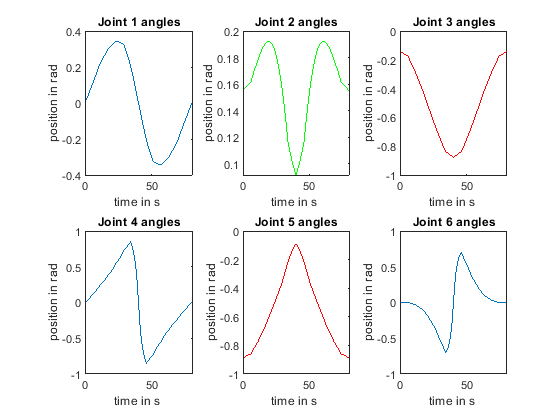

clf('reset')

for i = 1:m
    for j = 1:6
    if J_angles(i,j) < 1e-7 && J_angles(i,j) > -1e-7
       J_angles(i,j) = 0;
    end
    end
end

% not using this atm
% Angles we will send to robot
J_angles_2 = zeros(m+1,6);

%% functions to resize our array of joint angles
idx = 1:(m); % Index 
idxq = linspace(min(idx), max(idx),(m+1));% Interpolation Vector
% Here we resize our array of m joint angles to array of m+1 joint angles
% We must do that beacause we know our movement lasts m x time_step
% For the robot to move from position 1 to 2 it would use speed in array 1.
% For movement from (m-1) to m it would use (m-1) speed array.That leaves our m speed array unusued
% that leaves us with one less m step . So our movement would be (m-1) x time_step
% thats why we resize our joint angles to m+1 so we can use that m speed array.
for i = 1:6
J_angles_2(:,i) = interp1(idx, J_angles(:,i), idxq, 'linear');  
end

figure(3)
subplot(2,3,1); % used to create multiple plots side by side
plot(J_angles(:,1))
title('Joint 1 angles')
xlabel('time in s ')
ylabel('position in rad')

subplot(2,3,2);
plot(J_angles(:,2),'color','g')
title('Joint 2 angles')
xlabel('time in s ')
ylabel('position in rad')

subplot(2,3,3);
plot(J_angles(:,3),'color','r')
title('Joint 3 angles')
xlabel('time in s ')
ylabel('position in rad')

subplot(2,3,4);
plot(J_angles(:,4))
title('Joint 4 angles')
xlabel('time in s ')
ylabel('position in rad')

subplot(2,3,5);
plot(J_angles(:,5),'color','r')
title('Joint 5 angles')
xlabel('time in s ')
ylabel('position in rad')

subplot(2,3,6);
plot(J_angles(:,6))
title('Joint 6 angles')
xlabel('time in s ')
ylabel('position in rad')


%% fill in one spot in array of angles , only if top function does not fail completely
if y_1 < 2 && error_ == 1
   mat = transl(x(err(1),1),x(err(1),2),x(err(1),3))*TR(:,:,err(1));
   HG_matrix(:,:,err(1)) = mat; 
   angle_ = robot.ikunc(HG_matrix(:,:,err(1)));
   J_angles_(err(1),:) = angle_;
    
end


%%Second method if first one fails,takes 4-5 times more time
now2 = tic();
if error_ == 1 && y_1 >= 2
    for i = 1:m
        mat = transl(x(i,1),x(i,2),x(i,3))*TR(:,:,i);
        HG_matrix(:,:,i) = mat;
        angle_ = robot.ikunc(HG_matrix(:,:,i));
        J_angles(i,:) = angle_;
    end
end

time2 = toc(now2)

time2 = 0.0036

# Plot motor velocity

- If velocity is to small we ignore it 

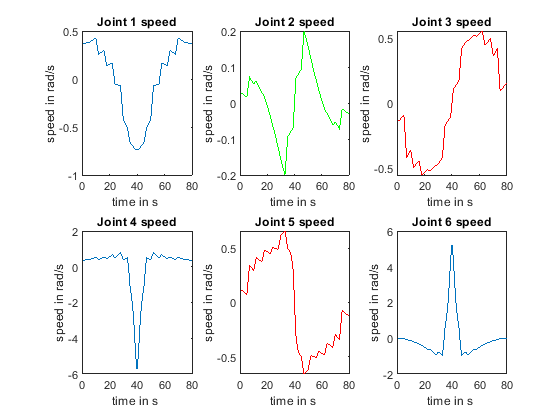

for i = 1:6
J_speed(:,i) = gradient(J_angles(:,i)/time_step);
end

for i = 1:m
 for j = 1:6
    if J_speed(i,j) < 1e-7 && J_speed(i,j) > -1e-7
       J_speed(i,j) = 0;
    end
 end
end

clf
figure(4)
subplot(2,3,1); % used to create multiple plots side by side
plot(J_speed(:,1))
title('Joint 1 speed')
xlabel('time in s ')
ylabel('speed in rad/s')

subplot(2,3,2);
plot(J_speed(:,2),'color','g')
title('Joint 2 speed')
xlabel('time in s ')
ylabel('speed in rad/s')

subplot(2,3,3);
plot(J_speed(:,3),'color','r')
title('Joint 3 speed')
xlabel('time in s ')
ylabel('speed in rad/s')

subplot(2,3,4);
plot(J_speed(:,4))
title('Joint 4 speed')
xlabel('time in s ')
ylabel('speed in rad/s')

subplot(2,3,5);
plot(J_speed(:,5),'color','r')
title('Joint 5 speed')
xlabel('time in s ')
ylabel('speed in rad/s')

subplot(2,3,6);
plot(J_speed(:,6))
title('Joint 6 speed')
xlabel('time in s ')
ylabel('speed in rad/s')